# Forecasting of coronavirus COVID19 epidemic (SIR model)

It is assumed that the model is a reasonable description of the one-stage epidemic. In particular, the model assumes a constant population, uniform mixing of the people, and equally likely recovery of infected. The model is data-driven, so its forecast is as good as data are. The forecasting change with new or changed data.

**DISCLAIMER**: Software and data is for education and not for medical or commercial. The model may fail in some situations. In particular, the model may be unadequate, the model may fail in the initial phase and in when additional epidemic stages or outbreaks  (not described by SIR model) are encountered. Use it at your own discretion.

**Source of data**

[https://ourworldindata.org/coronavirus-source-data.](https://ourworldindata.org/coronavirus-source-data.)

[https://www.worldometers.info/coronavirus/coronavirus-cases/#case-tot-outchina](https://www.worldometers.info/coronavirus/coronavirus-cases/#case-tot-outchina)

[https://en.wikipedia.org/wiki/2019%E2%80%9320_coronavirus_pandemic_by_country_and_territory](https://en.wikipedia.org/wiki/2019%E2%80%9320_coronavirus_pandemic_by_country_and_territory)

An actual source of data is for each country reported in the corresponding getData function.

**Report**

fprintf('Date: %s\n',datestr(date))  

Date: 26-Mar-2020


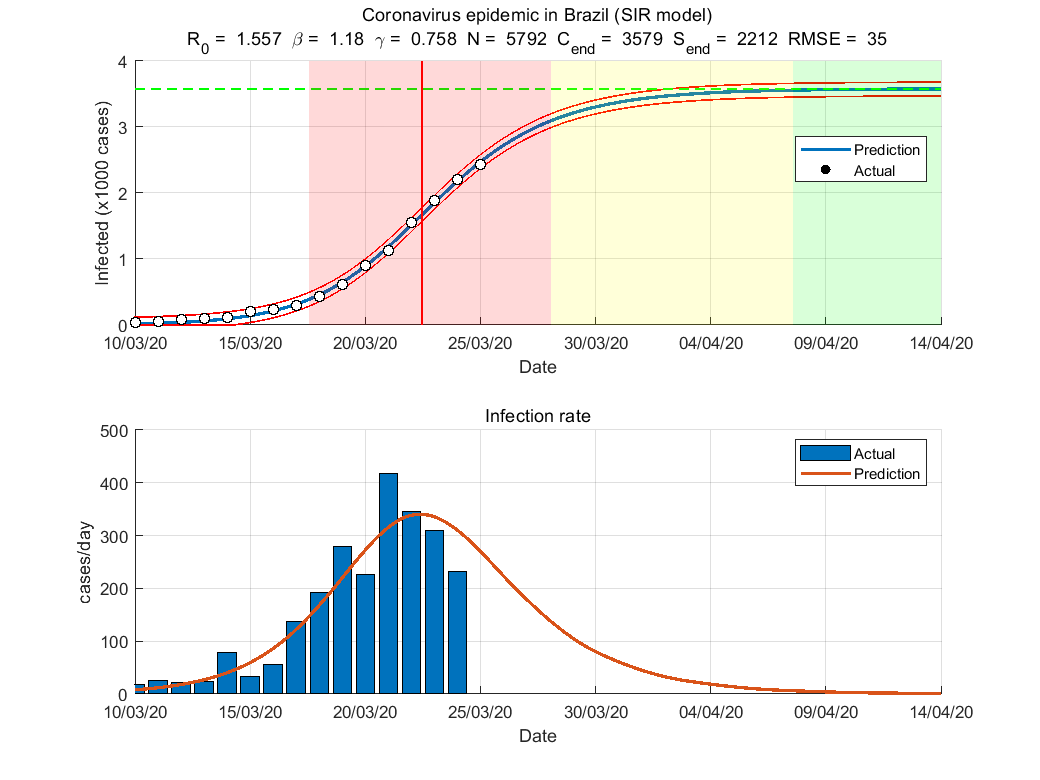

Epidemic modeling by susceptible-infected-recovered (SIR) model
  Country                       Brazil
  Day                           20
Estimated the SIR model parameters
  Contact rate (beta)           1.18 (1/day)
  Removal rate (gamma)          0.758 (1/day)
  Population size (N)           5791
  Initial number of cases (I0)  1
Basic reproduction number (R0)  1.557
Final state
  Final number of cases         3579
  Final number of susceptibles  2212
Daily forcast for 26-Mar-2020
  Total                         2720
  Increase                      249
Estimated logistic model parameters
  Epidemic size (K)             3051 (cases)
  Epidemic rate (r)             0.421913 (1/day)
  Initial doubling time         1.6 (day)
Estimated duration (days)
  Turning day                   16
  Acceleration   phase          5 (days)
  Deaceleration  phsee          6 (days)
  Total duration                11 (days)
Estimated datums
  Outbreak                      06-Mar-2020
  Start of accelerat

aut = fitVirusCV19(@getDataBrazil,'prn','on','nmax',1e5);